# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
anovaStimLevel = [];
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
% which 
conf = 'CSNESiteVisit';
%conf = 'NeuroModulation';
%conf = 'NeuroModulationV2';

%conf = 'NeuroModulationV3';
%conf = 'NeuroModulationV4';
% 6/17/_2016 try neuromdoulation 
for i = 2:length(SIDS)-4
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
                        typeCell = {'180'};
           stimLevel = 2500;

        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
                 stimLevel = 3000;

        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
                       stimLevel = 3500;

        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
         stimLevel = 750;

        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
                  stimLevel = 750;
   
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
                            stimLevel = 1750;
  
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'0b5a2eepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
                              stimLevel = 1750;

            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
                                          stimLevel = 1750;

            
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{betaChan});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = []; 
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                

                            if (strcmp(conf,'NeuroModulation') | strcmp(conf,'NeuroModulationV2')| strcmp(conf,'NeuroModulationV4')  | strcmp(conf,'NeuroModulationV3')) & strcmp(answer,'zscore')
                tB = [tB tempBase'];
                t1 = [t1 tempResp1'];
                t2 = [t2 tempResp2'];
                t3 = [t3 tempResp3'];
                            else
                            tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
            end
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
            
            lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
            vecType = repmat(typeCell{i},lengthType,1);
            vecTypeC = cellstr(vecType)';
            anovaType = [anovaType{:} vecTypeC];
            
            % 6-17-2016 - have to transpose for 'conf'
                            if (strcmp(conf,'NeuroModulation')| strcmp(conf,'NeuroModulationV4') | strcmp(conf,'NeuroModulationV2')  | strcmp(conf,'NeuroModulationV3')) & strcmp(answer,'zscore')
                           typeResp = [tempResp3' tempResp2' tempResp1' tempBase'];
            else
            typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
            end
            anovaTotalMags = [anovaTotalMags typeResp];
            num5S = repmat('Ct>=5',length(tempResp3),1);
            num3S= repmat('3<=Ct<=4',length(tempResp2),1);
            num1S = repmat('1<=Ct<=2',length(tempResp1),1);
            numBaseS = repmat('Base',length(tempBase),1);
            
            %             numNullS = repmat('Null',length(tN),1);
            
            b5C = cellstr(num5S)';
            b3C = cellstr(num3S)';
            b1C = cellstr(num1S)';
            BC = cellstr(numBaseS)';
%             nC = cellstr(numNullS)';
            anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
        anovaStimLevel = [anovaStimLevel repmat(stimLevel,lengthToRep,1)'];
       % anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
         %       anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
             % anovaType = [anovaType typeNums];
        
        
    end
end

sid = 'd5cd55'

anovaStimLevel =         2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500


sid = 'c91479'

anovaStimLevel =         2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500


sid = '7dbdec'

anovaStimLevel =         2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500


sid = '9ab7ab'

anovaStimLevel =         2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500


sid = '702d24'

anovaStimLevel =         2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500


sid = 'ecb43e'

anovaStimLevel =         2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500


sid = '0b5a2e'

anovaStimLevel =         2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500        2500


%     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
%     [c,m,h,gnames] = multcompare(stats);


tableBetaStim = table(anovaTotalMags',anovaStimLevel',categorical(anovaNumStims)',categorical(anovaBetaSID)',...
    'VariableNames',{'Magnitude','stimLevel','NumStims','SID'});
glme = fitglme(tableBetaStim,'Magnitude~NumStims+stimLevel+(1|SID)',...
    'Distribution','Normal','Link','Identity','FitMethod','Laplace','DummyVarCoding','effects')

glme = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations            9204
    Fixed effects coefficients           5
    Random effects coefficients          7
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       Laplace

Formula:
    Magnitude ~ 1 + stimLevel + NumStims + (1 | SID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    81660    81710    -40823           81646   

Fixed effects coefficients (95% CIs):
    Name                       Estimate     SE          tStat      DF      pValue        Lower        Upper   
    '(Intercept)'                  84.05      26.924     3.1218    9199     0.0018032       31.273      136.83
    'stimLevel'                0.0056822    0.012084    0.47024    9199       0.63819    -0.

disp(glme)


Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations            9204
    Fixed effects coefficients           5
    Random effects coefficients          7
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       Laplace

Formula:
    Magnitude ~ 1 + stimLevel + NumStims + (1 | SID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    81660    81710    -40823           81646   

Fixed effects coefficients (95% CIs):
    Name                       Estimate     SE      
    '(Intercept)'                  84.05      26.924
    'stimLevel'                0.0056822    0.012084
    'NumStims_1<=Ct<=2'          0.84993     0.33679
    'NumStims_3<=Ct<=4'           1.4776     0.42174
    'NumStims_Base'              -5.4781     0.50705




anova(glme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                 FStat      DF1    DF2     pValue   
    '(Intercept)'         9.7455    1      9199    0.0018032
    'stimLevel'          0.22113    1      9199      0.63819
    'NumStims'             42.38    3      9199    3.431e-27


[psi,dispersion,stats] = covarianceParameters(glme)

psi = 1×1 cell array
    {[985.2795]}


dispersion = 414.3790

stats = 2×1 cell array
    {1×7 classreg.regr.lmeutils.titleddataset}
    {1×5 classreg.regr.lmeutils.titleddataset}


psi

psi = 1×1 cell array
    {[985.2795]}


dispersion

dispersion = 414.3790

stats

stats = 2×1 cell array
    {1×7 classreg.regr.lmeutils.titleddataset}
    {1×5 classreg.regr.lmeutils.titleddataset}


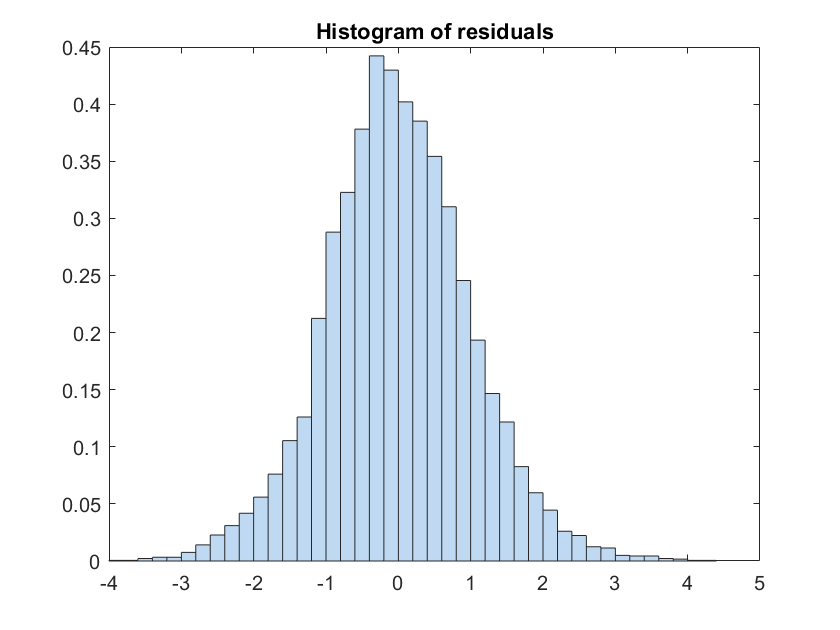


plotResiduals(glme,'histogram','ResidualType','Pearson')

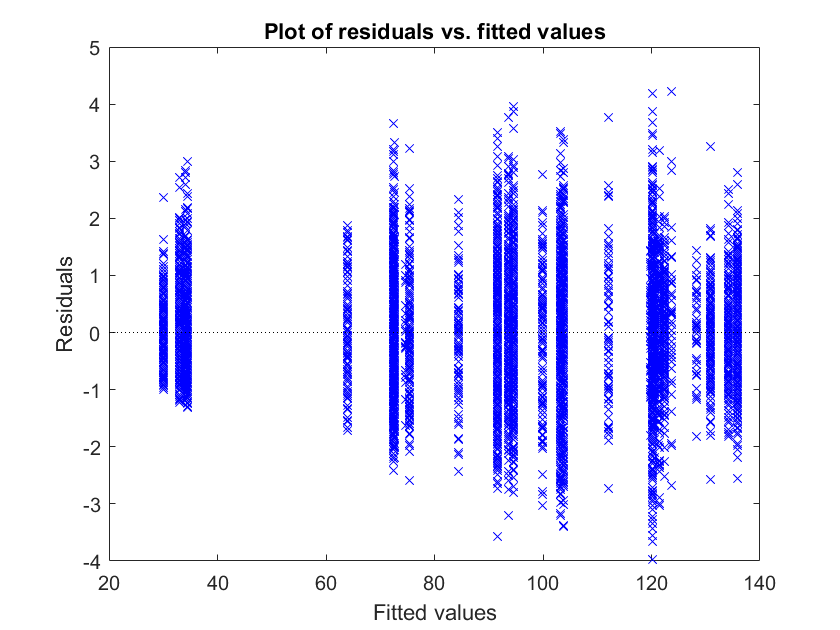

plotResiduals(glme,'fitted','ResidualType','Pearson')

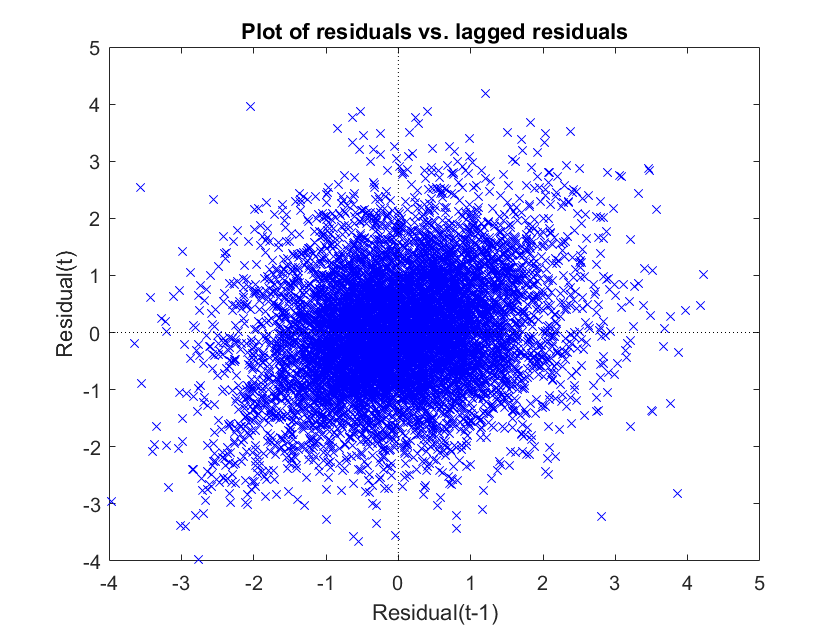

plotResiduals(glme,'lagged','ResidualType','Pearson')

tableBetaStim = table(anovaTotalMags',categorical(anovaType)',categorical(anovaNumStims)',categorical(anovaBetaSID)',...
    'VariableNames',{'Magnitude','Type','NumStims','SID'});
glme = fitglme(tableBetaStim,'Magnitude~NumStims+Type+(Type|SID)+(NumStims|SID)',...
    'Distribution','Normal','Link','Identity','FitMethod','Laplace','DummyVarCoding','effects')

glme = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations            9204
    Fixed effects coefficients           8
    Random effects coefficients         63
    Covariance parameters               26
    Distribution                    Normal
    Link                            Identity
    FitMethod                       Laplace

Formula:
    Magnitude ~ 1 + Type + NumStims + (1 + Type | SID) + (1 + NumStims | SID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    81631    81874    -40782           81563   

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE         tStat        DF      pValue        Lower       Upper  
    '(Intercept)'                96.325     8.6431       11.145    9196    1.1596e-28      79.382     113.27
    'Type_0'                    -23.561     8.6359      -2.7282    9196

disp(glme)


Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations            9204
    Fixed effects coefficients           8
    Random effects coefficients         63
    Covariance parameters               26
    Distribution                    Normal
    Link                            Identity
    FitMethod                       Laplace

Formula:
    Linear Mixed Formula with 3 predictors.

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    81631    81874    -40782           81563   

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE     
    '(Intercept)'                96.325     8.6431
    'Type_0'                    -23.561     8.6359
    'Type_180'                  -3.2726     12.569
    'Type_270'                 -0.70523     11.276
    'Type_90'                   0.86574     9.7337
    'NumStims_1<=Ct<=2'

anova(glme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                 FStat     DF1    DF2     pValue     
    '(Intercept)'         124.2    1      9196     1.1596e-28
    'Type'               362.63    4      9196    2.1253e-290
    'NumStims'           4.7997    3      9196      0.0024211


[psi,dispersion,stats] = covarianceParameters(glme)

psi = 2×1 cell array
    {5×5 double}
    {4×4 double}


dispersion = 409.2471

stats = 3×1 cell array
    {15×7 classreg.regr.lmeutils.titleddataset}
    {10×7 classreg.regr.lmeutils.titleddataset}
    { 1×5 classreg.regr.lmeutils.titleddataset}


psi

psi = 2×1 cell array
    {5×5 double}
    {4×4 double}


dispersion

dispersion = 409.2471

stats

stats = 3×1 cell array
    {15×7 classreg.regr.lmeutils.titleddataset}
    {10×7 classreg.regr.lmeutils.titleddataset}
    { 1×5 classreg.regr.lmeutils.titleddataset}


% DJC - 1-5-2018 - add in table, repeated mesaures ANOVA
tableBetaStim = table(anovaBetaSID,anovaBetaBase,anovaBetaMags1,anovaBetaMags3,anovaBetaMags5,...
    'VariableNames',{'SID','base','low','med','high'});
rm = fitrm(tableBetaStim,'base-high~SID','WithinDesign',[1 2 3 4])

Subscripted assignment dimension mismatch.

Error in classreg.regr.modelutils.designmatrix (line 324)
    X(:,colsj) = Xj;

Error in RepeatedMeasuresModel.fit (line 1326)
                = classreg.regr.modelutils.designmatrix(ds(~missing,:),...

Error in 

p =    1.0e-16 *

    0.0000
         0
    0.1021


tbl = 6×7 cell array
    'Source'                        'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'             'Prob>F'    
    'anovaNumStims'                 [6.1036e+04]    [   3]    [        0]    [2.0345e+04]    [   50.8356]    [1.4081e-32]
    'anovaBetaSID'                  [6.7916e+06]    [   6]    [        0]    [1.1319e+06]    [2.8283e+03]    [         0]
    'anovaNumStims*anovaBetaSID'    [4.9615e+04]    [  18]    [        0]    [2.7564e+03]    [    6.8872]    [1.0210e-17]
    'Error'                         [3.6724e+06]    [9176]    [        0]    [  400.2208]              []              []
    'Total'                         [1.2500e+07]    [9203]    [        0]              []              []              []


stats = struct with fields:
         source: 'anovan'
          resid: [9204×1 double]
         coeffs: [40×1 double]
            Rtr: [28×28 double]
       rowbasis: [28×40 double]
            dfe: 9176
            mse: 400.2208
    nullproject: [40×28 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {40×1 cell}
           vars: [40×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


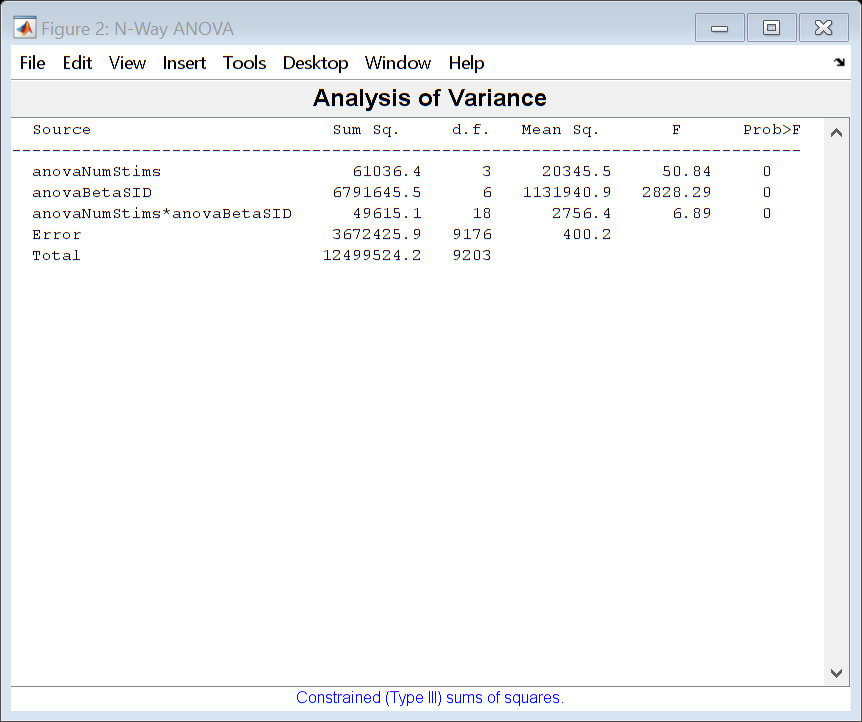

close all;
figure
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType,anovaBetaSID},'varnames',{'anovaType','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])
%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'})
% 
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType},'varnames',{'anovaType'})
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])
%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})
% [p,tbl,stats] = anovan(anova2,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})
% 

%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'},'model','interaction')

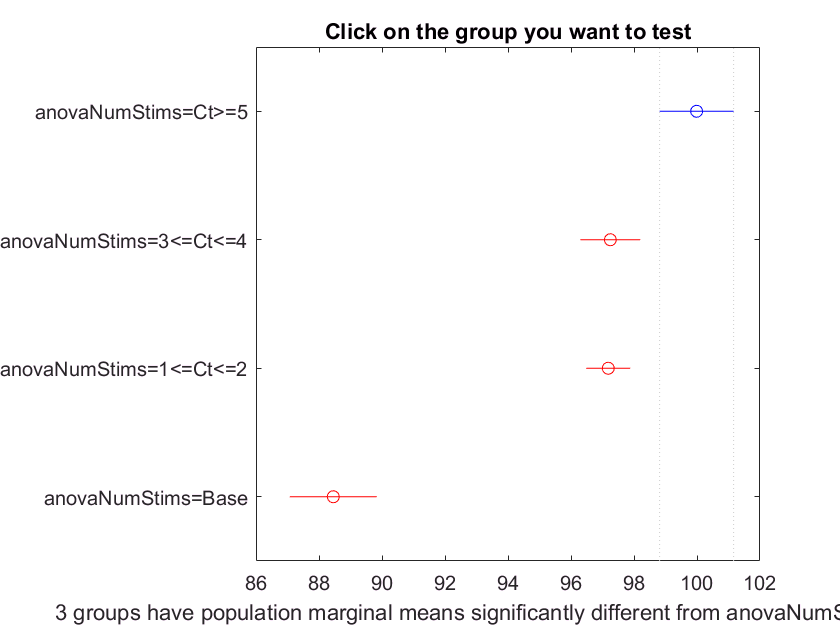

c =     1.0000    2.0000    0.5947    2.7393    4.8838    0.0057
    1.0000    3.0000    0.9238    2.8052    4.6866    0.0007
    1.0000    4.0000    9.0071   11.5344   14.0618    0.0000
    2.0000    3.0000   -1.5536    0.0659    1.6854    0.9996
    2.0000    4.0000    6.4562    8.7952   11.1341    0.0000
    3.0000    4.0000    6.6290    8.7292   10.8295    0.0000


m =    99.9879    0.6464
   97.2486    0.5282
   97.1827    0.3441
   88.4535    0.7416


h =   Figure (3: Multiple comparison of population marginal means) with properties:

      Number: 3
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


gnames = 4×1 cell array
    'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'


%[p,tbl,stats] = anova2(anovaTotalMags,anovaBetaSID)

figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans = 4×3 cell array
    'anovaNumStims=Ct>=5'       [99.9879]    [0.6464]
    'anovaNumStims=3<=Ct<=4'    [97.2486]    [0.5282]
    'anovaNumStims=1<=Ct<=2'    [97.1827]    [0.3441]
    'anovaNumStims=Base'        [88.4535]    [0.7416]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),flip(m(:,1)),flip(m(:,2)),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('CCEP Magnitude (\muV)','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [86 102]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [86 102]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


ax.FontSize = 12;

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [86 102]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


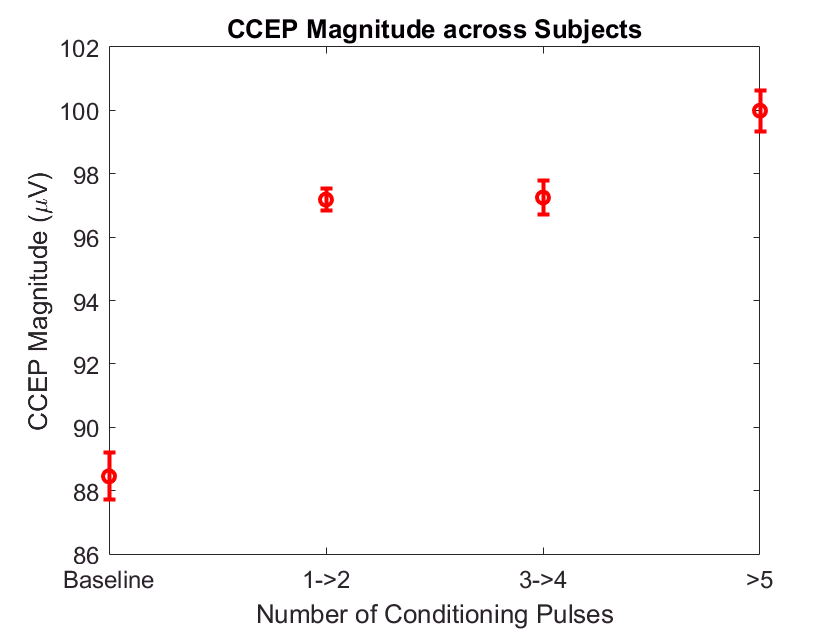


load('line_colormap.mat');
colors = cm(round(linspace(1, size(cm, 1), length(m))), :);

% ax.FontWeight = 'bold';
ax.XTickLabel = {'','Baseline','1->2','3->4','>5',''}

title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

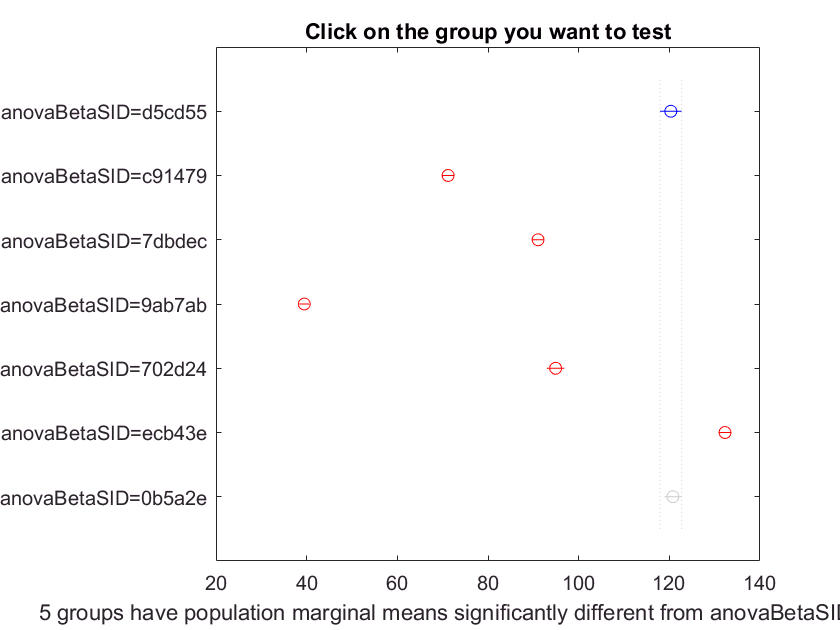

results1 =     1.0000    2.0000   45.4835   49.1277   52.7719    0.0000
    1.0000    3.0000   25.5524   29.2792   33.0059    0.0000
    1.0000    4.0000   77.2706   80.8464   84.4223    0.0000
    1.0000    5.0000   21.2013   25.4089   29.6165    0.0000
    1.0000    6.0000  -15.6812  -11.9550   -8.2288    0.0000
    1.0000    7.0000   -4.6010   -0.4589    3.6832    0.9999
    2.0000    3.0000  -22.3437  -19.8485  -17.3534    0.0000
    2.0000    4.0000   29.4551   31.7187   33.9823    0.0000
    2.0000    5.0000  -26.8876  -23.7188  -20.5500    0.0000
    2.0000    6.0000  -63.5770  -61.0827  -58.5884    0.0000



figure
results1 = multcompare(stats,'Dimension',[2])

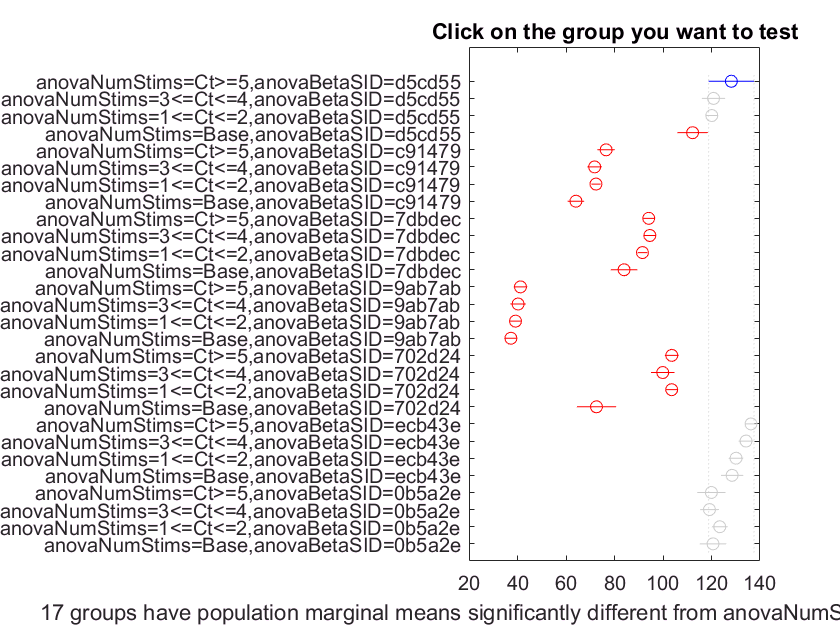

cM =     1.0000    2.0000   -6.3021    7.3406   20.9833    0.9716
    1.0000    3.0000   -4.2071    8.0654   20.3379    0.7907
    1.0000    4.0000    1.4108   15.9843   30.5578    0.0134
    1.0000    5.0000   38.7006   51.6340   64.5675    0.0000
    1.0000    6.0000   43.7407   56.3640   68.9872    0.0000
    1.0000    7.0000   43.7135   55.8163   67.9191    0.0000
    1.0000    8.0000   51.2572   64.0868   76.9164    0.0000
    1.0000    9.0000   21.6782   34.0523   46.4265    0.0000
    1.0000   10.0000   21.1623   33.5967   46.0311    0.0000
    1.0000   11.0000   24.4908   36.6345   48.7783    0.0000


mM =   128.1727    3.2034
  120.8321    1.7965
  120.1073    0.8087
  112.1883    2.2652
   76.5386    1.3644
   71.8087    1.1344
   72.3564    0.5951
   64.0858    1.2914
   94.1203    0.9141
   94.5760    0.9716


hM =   Figure (6: Multiple comparison of population marginal means) with properties:

      Number: 6
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


gnamesM = 28×1 cell array
    'anovaNumStims=Ct>=5,anovaBetaSID=d5cd55'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=d5cd55'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=d5cd55'
    'anovaNumStims=Base,anovaBetaSID=d5cd55'
    'anovaNumStims=Ct>=5,anovaBetaSID=c91479'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=c91479'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=c91479'
    'anovaNumStims=Base,anovaBetaSID=c91479'
    'anovaNumStims=Ct>=5,anovaBetaSID=7dbdec'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=7dbdec'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=7dbdec'
    'anovaNumStims=Base,anovaBetaSID=7dbdec'
    'anovaNumStims=Ct>=5,anovaBetaSID=9ab7ab'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=9ab7ab'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=9ab7ab'
    'anovaNumStims=Base,anovaBetaSID=9ab7ab'
    'anovaNumStims=Ct>=5,anovaBetaSID=702d24'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=702d24'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=702d24'
    'anovaNumStims=Base,anovaBetaSID=702d24'
    'anovaNumStims=Ct>=5,anov



% figure
% results = multcompare(stats,'Dimension',[3])

figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])

errorbar((1:length(mM(:,1))),flip(mM(:,1)),flip(mM(:,2)),'ro','linestyle','none','linew',2','color','r')
ylabel('CCEP Magnitude (\muV)','fontsize',14,'fontweight','bold')
xlabel('Subject subdivided by number of conditioning pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes with properties:

             XLim: [0 30]
             YLim: [20 140]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


ax.XTick = []

ax =   Axes with properties:

             XLim: [0 30]
             YLim: [20 140]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


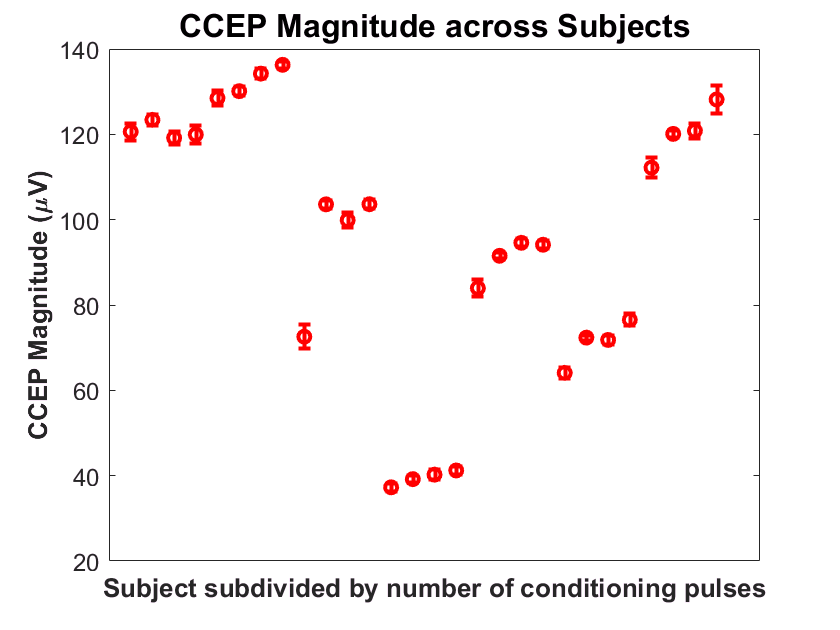

%ax.XTickLabel = {'Baseline','1->2','3->4','>5' }
ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

ans =     1.0000    2.0000    0.5947    2.7393    4.8838    0.0057
    1.0000    3.0000    0.9238    2.8052    4.6866    0.0007
    1.0000    4.0000    9.0071   11.5344   14.0618    0.0000
    2.0000    3.0000   -1.5536    0.0659    1.6854    0.9996
    2.0000    4.0000    6.4562    8.7952   11.1341    0.0000
    3.0000    4.0000    6.6290    8.7292   10.8295    0.0000



figure
multcompare(stats,'Dimension',[1])